# **Household's Constrained Labor and Savings Problem**

[**Back to Fan's Math for Economist Table of Content**](https://fanwangecon.github.io/Math4Econ/)

We previously solved for the unconstrained household's savings and borrowing problem: [unconstrained problem](https://fanwangecon.github.io/Math4Econ/derivative_application/K_save_households.html). And we previously solved for the constrained savings and borrowing problem for the household without labor: [Constrained Household Borrowing](https://fanwangecon.github.io/Math4Econ/optimization_application/household_borrow_constrained.html).

## What is the constrained asset choice problem with labor?

We have endowments in two periods, $Z_1$ and $Z_2$. Households can choose to work or have leisure. Think about the first period as the young period, the second period as the old period (retirement). Your wage in the first period could be used for first period consumption or saved for consumption in retirement.

- **Utility**: $U(c_{today}, c_{tomrrow}) = \log(c_{today}) + \psi \log(\text{leisure})+ 0.95 \cdot \log(c_{tomorrow})$

- **Budget Today**: $c_{today} + b = Z + w \cdot \text{work}$

- **Budget Tomorrow**: $c_{tomorrow} = b\cdot (1+ r ) + 2\cdot Z$

$w$ is the wage, and $b$ can be positive or negative. 

## Inequality Constraint

We can formulate the constrained problem as this:

- specifically: $\max_{b, \text{work}, \text{leisure}} \log(Z_1 + w\cdot \text{work}-b) + \psi \log(\text{leisure}) +  \beta \cdot \log(Z_2 + b\cdot (1+r))$

And the constraints are:

- 
$$b\ge \bar{b}$$


- 
$$\text{work} \ge 0$$


- 
$$\text{leisure}\ge 0$$


- $\text{work} + \text{leisure} \le T$, where $T$ is total time available

## Formulating the Constraints as a System of Linear Equations

Matlab has a conveninent function that solves any constrained maximization problem, ***fmincon***, we used it for one choice and one constraint before:[Constrained Household Borrowing](https://fanwangecon.github.io/Math4Econ/optimization_application/household_borrow_constrained.html). Now we have four constraints and three choice variables, we write them all as less than or equal to:

- 
$$\bar{b} - b \le 0$$


- 
$$- \text{work} \le 0$$


- 
$$- \text{leisure} \le 0$$


- 
$$\text{work} + \text{leisure} \le T$$


This is actually a linear system, the equations above are equal to:

- 
$$(-1)\cdot b + 0 \cdot \text{work} + 0 \cdot \text{leisure} \le - \bar{b}$$


- 
$$0 \cdot b + (-1) \cdot \text{work} + 0 \cdot \text{leisure} \le 0$$


- 
$$0 \cdot b + 0 \cdot \text{work} + (-1) \cdot \text{leisure} \le 0$$


- 
$$0 \cdot b + 1 \cdot \text{work} + 1 \cdot \text{leisure} \le T$$


Which mean that we have a $A$ matrix and $q$ vector:

- 
$$\left[ {\begin{array}{ccc} -1 & 0 & 0 \\  0 & -1 & 0 \\  0 & 0 & -1 \\  0 & 1 & 1 \end{array} } \right] \cdot \left[ {\begin{array}{c} b \\ \text{work} \\ \text{leisure} \end{array} } \right] \le \left[ {\begin{array}{c} - \bar{b} \\ 0 \\ 0 \\ T \end{array} } \right]$$


beta = 0.95;
z1 = 1;
z2 = 2;
r = 1.05;
syms c1 c2 mu
% The Lagrangian
lagrangian = (log(c1) + beta*log(c2)) - mu*( c2 + (1+r)*c1 - z1*(1+r) - z2)

$$lagrangian = \log\left(c_{1}\right)+\frac{19\,\log\left(c_{2}\right)}{20}-\mu \,\left(\frac{41\,c_{1}}{20}+c_{2}-\frac{81}{20}\right)$$

GRADIENT_max = [d_lagrangian_c1; d_lagrangian_c2; d_lagrangian_mu]

solu = solve(GRADIENT_max(1)==0, GRADIENT_max(2)==0, GRADIENT_max(3)==0, c1, c2, mu, 'Real', true);

Undefined function or variable 'GRADIENT_max'.

solu_c1 = (solu.c1)


clear all
% Parameters
beta = 0.95;
psi = 0.5;
z1 = 1;
z2 = 2;
r = 1.05;
b_bar_num = -1; % borrow up to 1 dollar 
w = 2; % wage rate
T = 1; % think about time as share of time in a year
% Write down the objective function, we will define it as a function handle, negative utility for minimization
U_neg = @(x) -1*(log(z1 + w*x(2) - x(1)) + psi*log(x(3)) + beta*log(z2 + x(1)*(1+r)));
% Constraint dervied above
A = [-1,0,0;0,0,-1;0,-1,0;0,1,1];
q = [-b_bar_num;0;0;T];
b0 = [0,0.5,0.5]; % starting value to search for optimal choice
% U_neg_num = matlabFunction(subs(U_neg, {beta, z1, z2, r}, {beta_num, z1_num, z2_num, r_num}));
[x_opti,U_at_b_opti] = fmincon(U_neg, b0, A, q);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 


b_opti = x_opti(1);
work_opti = x_opti(2);
leisure_opti = x_opti(3);
table(b_opti, work_opti, leisure_opti)

ans = 1×3 table
    b_opti     work_opti    leisure_opti
    _______    _________    ____________

    0.56595     0.59433       0.40567   


## Solve in Matlab using Fmincon

Define the parameters and the equations. Given our parameters here, our optimal choice is to save 0.56, work 0.59, and have 0.41 of leisure.


$$\left[ {\begin{array}{ccccccc} -1 & 0 & 0 & 0 & 0 & 0 & 0 \\  0 & -1 & 0 & 0 & 0 & 0 & 0 \\  0 & 0 & -1 & 0 & 0 & 0 & 0\\  0 & 1 & 1 & 0 & 0 & 0 & 0 \\  0 & 0 & 0 & -1 & 0 & 0 & 0 \\  0 & 0 & 0 & 0 & -1 & 0 & 0 \\  0 & 0 & 0 & 0 & 0 & -1 & 0 \\  0 & 0 & 0 & 0 & 0 & 0 & -1 \end{array} } \right] \cdot \left[ {\begin{array}{c} b \\ \text{work} \\ \text{leisure} \\ c_1 \\ c_2 \\ \mu_1 \\ \mu_2 \end{array} } \right] \le \left[ {\begin{array}{c} - \bar{b} \\ 0 \\ 0 \\ T \\ 0 \\ 0 \\ 0 \\ 0 \end{array} } \right]$$


clear all
% Parameters
beta = 0.95;
psi = 0.5;
z1 = 1;
z2 = 2;
r = 1.05;
b_bar_num = -1; % borrow up to 1 dollar
w = 2; % wage rate
T = 1; % think about time as share of time in a year

% problem with c1 c2 mu1 mu2 and work and leisure no b
% Write down the objective function, we will define it as a function handle, negative utility for minimization
U_neg = @(x) -1*(log(x(4)) + psi*log(x(3)) + beta*log(x(5)) - x(6)*( x(1) + x(4) - z1 - w*x(2)) - x(7)*(x(5) - z2 - (1+r)*x(1)));
b0 = [0.5, 0.5, 1.5, 1.5, 0.1, 0.1];
[x_opti,U_at_b_opti]  = fminunc(U_neg, b0);

Undefined function or variable 'b0'.

% Constraint dervied above
A = [-1,0,0,0,0,0,0;...
      0,-1,0,0,0,0;...
      0,0,-1,0,0,0,0;...
      0,0,0,-1,0,0,0 ;...
      0,0,0,0,-1,0,0 ;...
      0,0,0,0,0,-1,0 ;...
      0,0,0,0,0,0,-1 ];
q = [-b_bar_num;0;0;0;0;0;0];



Aequality = [0,1,1,0,0,0,0]
qequality = [T];

Now call fminunc to solve

b0 = [0.5, 0.5, 0.5, 1.5, 1.5, 0.1, 0.1]; % starting value to search for optimal choice
% U_neg_num = matlabFunction(subs(U_neg, {beta, z1, z2, r}, {beta_num, z1_num, z2_num, r_num}));
[x_opti,U_at_b_opti] = fmincon(U_neg, b0, A, q, Aequality, qequality);
b_opti = x_opti(1);
work_opti = x_opti(2);
leisure_opti = x_opti(3);
c1_opti = x_opti(4);
c2_opti = x_opti(5);
mu1_opti = x_opti(6);
mu2_opti = x_opti(7);
table(b_opti, work_opti, leisure_opti, c1_opti, c2_opti, mu1_opti, mu2_opti)

## Solve in Matlab using Fmincon

Define the parameters and the equations. Given our parameters here, our optimal choice is to save 0.56, work 0.59, and have 0.41 of leisure.


$$\left[ {\begin{array}{ccccccc} -1 & 0 & 0 & 0 & 0 & 0 & 0 \\  0 & -1 & 0 & 0 & 0 & 0 & 0 \\  0 & 0 & -1 & 0 & 0 & 0 & 0\\  0 & 1 & 1 & 0 & 0 & 0 & 0 \\  0 & 0 & 0 & -1 & 0 & 0 & 0 \\  0 & 0 & 0 & 0 & -1 & 0 & 0 \\  0 & 0 & 0 & 0 & 0 & -1 & 0 \\  0 & 0 & 0 & 0 & 0 & 0 & -1 \end{array} } \right] \cdot \left[ {\begin{array}{c} b \\ \text{work} \\ \text{leisure} \\ c_1 \\ c_2 \\ \mu_1 \\ \mu_2 \end{array} } \right] \le \left[ {\begin{array}{c} - \bar{b} \\ 0 \\ 0 \\ T \\ 0 \\ 0 \\ 0 \\ 0 \end{array} } \right]$$


clear all
% Parameters
beta = 0.95;
psi = 0.5;
z1 = 1;
z2 = 2;
r = 1.05;
b_bar_num = -1; % borrow up to 1 dollar
w = 2; % wage rate
T = 1; % think about time as share of time in a year

% Write down the objective function, we will define it as a function handle, negative utility for minimization
U_neg = @(x) -1*(log(x(4)) + psi*log(x(3)) + beta*log(x(5)) - x(6)*( x(1) + x(4) - z1 - w*x(2)) - x(7)*(x(5) - z2 - (1+r)*x(1)));
% Constraint dervied above
A = [-1,0,0,0,0,0,0;...
      0,0,-1,0,0,0,0;...
      0,-1,0,0,0,0,0;...
      0,1,1,0,0,0,0 ;...
      0,0,0,-1,0,0,0 ;...
      0,0,0,0,-1,0,0 ;...
      0,0,0,0,0,-1,0 ;...
      0,0,0,0,0,0,-1 ];
q = [-b_bar_num;0;0;T;0;0;0;0];

Now call fminunc to solve

b0 = [0.5, 0.5, 0.5, 1.5, 1.5, 0.1, 0.1]; % starting value to search for optimal choice
% U_neg_num = matlabFunction(subs(U_neg, {beta, z1, z2, r}, {beta_num, z1_num, z2_num, r_num}));
[x_opti,U_at_b_opti] = fmincon(U_neg, b0, A, q);


Problem appears unbounded.

fmincon stopped because the objective function value is less than
the default value of the objective function limit and constraints 
are satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



b_opti = x_opti(1);
work_opti = x_opti(2);
leisure_opti = x_opti(3);
c1_opti = x_opti(4);
c2_opti = x_opti(5);
mu1_opti = x_opti(6);
mu2_opti = x_opti(7);
table(b_opti, work_opti, leisure_opti, c1_opti, c2_opti, mu1_opti, mu2_opti)

ans = 1×7 table
      b_opti      work_opti    leisure_opti     c1_opti       c2_opti       mu1_opti      mu2_opti 
    __________    _________    ____________    __________    __________    __________    __________

    1.2919e+10     0.99893      1.2008e-13     1.7371e-05    2.0213e-08    2.1071e-10    1.2919e+10


## Solve in Matlab using Fmincon

Define the parameters and the equations. Given our parameters here, our optimal choice is to save 0.56, work 0.59, and have 0.41 of leisure.

clear all
% Parameters
beta = 0.95;
psi = 0.5;
z1 = 1;
z2 = 2;
r = 1.05;
b_bar_num = -1; % borrow up to 1 dollar
w = 2; % wage rate
T = 1; % think about time as share of time in a year

% Write down the objective function, we will define it as a function handle, negative utility for minimization
U_neg = @(x) -1*(log(z1 + w*x(2) - x(1)) + psi*log(x(3)) + beta*log(z2 + x(1)*(1+r)));
% Constraint dervied above
A = [-1,0,0;0,0,-1;0,-1,0;0,1,1];
q = [-b_bar_num;0;0;T];

Now call fminunc to solve

b0 = [0,0.5,0.5]; % starting value to search for optimal choice
% U_neg_num = matlabFunction(subs(U_neg, {beta, z1, z2, r}, {beta_num, z1_num, z2_num, r_num}));
[x_opti,U_at_b_opti] = fmincon(U_neg, b0, A, q);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

b_opti = x_opti(1);
work_opti = x_opti(2);
leisure_opti = x_opti(3);
table(b_opti, work_opti, leisure_opti)

ans = 1×3 table
    b_opti     work_opti    leisure_opti
    _______    _________    ____________

    0.56595     0.59433       0.40567   


## Effects of $\psi$ on optimal choices

How does optimal choice change if the preference for leisure is different? What does the optimal borrowing and savings choice stop shifting when work hour choice constraint becomes binding?

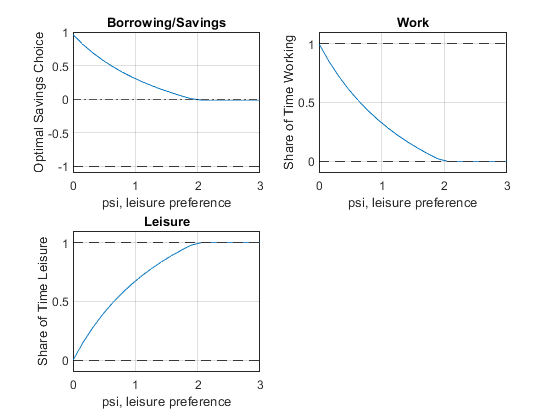

% Create a vector of Z2, so Z2 fector starts at the same value as Z1*0.5 going up to 4 times Z1
psi_vec = linspace(0, 3, 20);
% A vector to store optimal choices
b_opti_vec = zeros(size(psi_vec));
work_opti_vec = zeros(size(psi_vec));
leisure_opti_vec = zeros(size(psi_vec));
% Solving for optimal choices as we change Z2
for i=1:1:length(psi_vec)
    U_neg = @(x) -1*(log(z1 + w*x(2) - x(1)) + psi_vec(i)*log(x(3)) + beta*log(z2 + x(1)*(1+r)));
    options = optimoptions('FMINCON','Display','off');
    [x_opti,U_at_x_opti] = fmincon(U_neg, b0, A, q, [], [], [], [], [], options);
    b_opti_vec(i) = x_opti(1);
    work_opti_vec(i) = x_opti(2);
    leisure_opti_vec(i) = x_opti(3);
end

% Plot Results
figure()
subplot(2,2,1)
plot(psi_vec, b_opti_vec)
ylim([-1.1 1]);
hold on
plot(psi_vec,ones(size(psi_vec)) * 0, 'k-.');
plot(psi_vec,ones(size(psi_vec)) * -1, 'k--');
grid on;
title('Borrowing/Savings')
ylabel('Optimal Savings Choice')
xlabel('psi, leisure preference')
subplot(2,2,2)
plot(psi_vec, work_opti_vec)
ylim([-0.1 1.1]);
hold on;
plot(psi_vec,ones(size(psi_vec)) * 1, 'k--');
plot(psi_vec,ones(size(psi_vec)) * 0, 'k--');
grid on;
title('Work')
ylabel('Share of Time Working')
xlabel('psi, leisure preference')
subplot(2,2,3)
plot(psi_vec, leisure_opti_vec)
ylim([-0.1 1.1]);
hold on;
plot(psi_vec,ones(size(psi_vec)) * 1, 'k--');
plot(psi_vec,ones(size(psi_vec)) * 0, 'k--');
grid on;
title('Leisure')
ylabel('Share of Time Leisure')
xlabel('psi, leisure preference')

## Effects of $r$ and $z_2$ on optimal choices

How does optimal choice change if the household has more endowment tomorrow and what if interest rate changes? See double loop below.

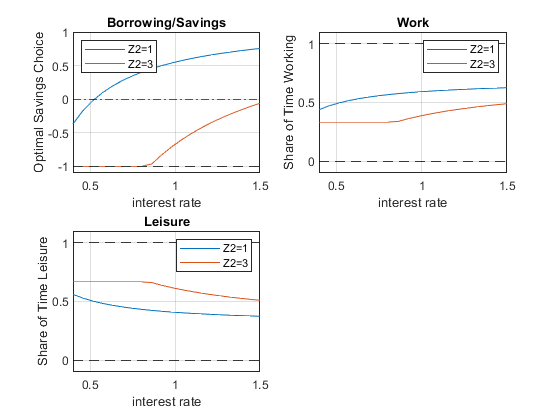

% Vector of interest rates
r_vec = linspace(0.4, 1.50, 20);
% Vector of Z2
Z2_vec = linspace(z1*1, z1*3, 2);
% A vector to store optimal choices
rows = length(r_vec);
cols = length(Z2_vec);
b_opti_mat = zeros(rows, cols);
work_opti_mat = zeros(rows, cols);
leisure_opti_mat = zeros(rows, cols);
% Solving for optimal choices as we change Z2
for j=1:1:length(Z2_vec)
    for i=1:1:length(r_vec)
        U_neg = @(x) -1*(log(z1 + w*x(2) - x(1)) + psi*log(x(3)) + beta*log(Z2_vec(j) + x(1)*r_vec(i)));
        options = optimoptions('FMINCON','Display','off');
        [x_opti,U_at_x_opti] = fmincon(U_neg, b0, A, q, [], [], [], [], [], options);
        b_opti_mat(i, j) = x_opti(1);
        work_opti_mat(i, j) = x_opti(2);
        leisure_opti_mat(i, j) = x_opti(3);
    end
end

% Plot Results
legendCell = cellstr(num2str(Z2_vec', 'Z2=%-d'));
figure()
subplot(2,2,1)
plot(r_vec, b_opti_mat)
ylim([-1.1 1]);
hold on
plot(r_vec,ones(size(r_vec)) * 0, 'k-.');
plot(r_vec,ones(size(r_vec)) * -1, 'k--');
grid on;
title('Borrowing/Savings')
ylabel('Optimal Savings Choice')
xlabel('interest rate')
legend(legendCell, 'Location','northwest');
subplot(2,2,2)
plot(r_vec, work_opti_mat)
ylim([-0.1 1.1]);
hold on;
plot(r_vec,ones(size(r_vec)) * 1, 'k--');
plot(r_vec,ones(size(r_vec)) * 0, 'k--');
grid on;
title('Work')
ylabel('Share of Time Working')
xlabel('interest rate')
legend(legendCell);
subplot(2,2,3)
plot(r_vec, leisure_opti_mat)
ylim([-0.1 1.1]);
hold on;
plot(r_vec,ones(size(r_vec)) * 1, 'k--');
plot(r_vec,ones(size(r_vec)) * 0, 'k--');
grid on;
title('Leisure')
ylabel('Share of Time Leisure')
xlabel('interest rate')
legend(legendCell);